%%%%%%%%%%%%%%%%%%%%%%
%%% plot all pollutant reductions from:
% 1. short-run fuel price impacts
% 2. CAIR impacts
% 3. CSAPR, MATS, and long-run fuel price impacts
% 4. total counterfactual impacts
% for all NYC sites (Bronx, Manhattan, Queens) to see differences between
% the three
%% importantly, the reductions are between the modeled actual and modeled counterfactual
%% epi studies use obs - (act - cf). We are doing this to stay consistent with them
%% uncertainty is entirely from the counterfactual, however, since the fixed portion is in the actual
%%% REMEMBER TO CLEAR THE IN-LINE OUTPUT AFTER PLOTTING
%%% created: 6/02/2023
%%%%%%%%%%%%%%%%%%%%%%

%% file paths
fp = fileparts(matlab.desktop.editor.getActiveFilename);
% directory with counterfactual air pollutants
rel_path_input_pollutants_short_cf = "../../Data/Counterfactual Air Pollutants/7. ba regions edited";
rel_path_input_pollutants_total_cf = "../../Data/Counterfactual Air Pollutants/8. total cf edited";
rel_path_input_pollutants_impact = "../../Data/Counterfactual Air Pollutants/7. ba regions edited";
% directory with observed emissions and pollutants
rel_path_observed = "../../Data/Analysis";
% directory with modeled actual pollutants
rel_path_actual = "../../Data/Counterfactual Air Pollutants/0. modeled actual";

% directory to plot outputs
rel_path_output = "../../Figures/for publication";

%% miscellaneous inputs for retrieving data
% naming conventions are all different, unfortunately
years_all = 2006:2019; % input one or a range of years (consecutive)
regions_emissions_all = ["ATL", "NYC"]; % for storing
fn_ends = {["GA", "AL", "FL", "MS"], ... % ATL regional
    ["CT", "NY", "PA", "NJ", "DE", "MD", "VA", ...
    "WV", "OH", "KY", "MI", "IL", "NC", "IN"]}; % NYC regional
% species to plot for ML (so that we can increase the number of species at
% a later time
target_names_all = ["pm25", "ozone"];
% label units to map to (must be parallel to target names)
label_units_all = ["(\mug/m^3)", "(ppb)"];
labelDictionary = containers.Map(target_names_all, label_units_all);
% sites to plot for ML
sites_ML_all = ["SDK", "Bronx", "Manhattan", "Queens"]; % choose site for NYC

%%%%%%%%%%%%%%%%%%%%%%
%%% import and process data
%%%%%%%%%%%%%%%%%%%%%%

%%% pre-allocate things to plot
pollutants_total_cf = struct();
pollutants_short_cf = struct();
pollutants_CAIR_cf = struct();
pollutants_other_cf = struct();
pollutants_total_diff = struct();
pollutants_short_diff = struct();
pollutants_CAIR_diff = struct();
pollutants_other_diff = struct();
pollutants_obs = struct();
pollutants_act = struct(); % modeled actual

%%% establish time spacing
spacing = datetime(years_all(1), 1, 1):calmonths(1):datetime(years_all(end)+1, 1, 1);
spacing = [spacing(1:end-1)', spacing(2:end)'-caldays(1)]; % start and end of bins
spacing = datenum(spacing); % to datenum for binning function

%%% loop through ML sites, import, process, and store all data
for i = 1:length(sites_ML_all)
    site = sites_ML_all(i);

    %% loop through species
    for j = 1:length(target_names_all)
        target = target_names_all(j);

        %% retrieve observed data
        cd(fp)
        cd(strcat(rel_path_observed, "/", site))
        pollutant_obs = readtable(...
            strcat(site, "_observed_modeled_timeseries_XGB.xlsx"),...
            "Sheet", strcat("y_", target), "VariableNamingRule", "preserve");
        %% retrieve counterfactual data
        cd(fp)
        cd(rel_path_input_pollutants_total_cf)
        pollutant_total_cf = parquetread(strcat(site, "_", target, "_", num2str(years_all(1)),...
            "-", num2str(years_all(end)), "_bin_daily.parquet"));
        cd(fp)
        cd(rel_path_input_pollutants_short_cf)
        pollutant_short_cf = parquetread(strcat(site, "_", target, "_", num2str(years_all(1)),...
            "-", num2str(years_all(end)), "_bin_daily.parquet"));
        %% retrieve impact data
        cd(fp)
        cd(rel_path_input_pollutants_impact)
        pollutant_CAIR_cf = parquetread(strcat(site, "_", target, "_", num2str(years_all(1)),...
            "-", num2str(years_all(end)), "_CAIR_bin_daily.parquet"));
        pollutant_other_cf = parquetread(strcat(site, "_", target, "_", num2str(years_all(1)),...
            "-", num2str(years_all(end)), "_other_bin_daily.parquet"));
        %% retrieve modeled actual data
        cd(fp)
        cd(rel_path_actual)
        pollutant_act = parquetread(strcat(site, "_", target, "_", num2str(years_all(1)),...
            "-", num2str(years_all(end)), "_bin_daily.parquet"));

        %% remove days where there is no observed data
        % observed
        inds = isnan(pollutant_obs.observed); % nan observations
        pollutant_obs(inds, :) = [];
        % counterfactual
        inds = ~ismember(pollutant_total_cf.Date, pollutant_obs.Date);
        pollutant_total_cf(inds, :) = [];
        inds = ~ismember(pollutant_short_cf.Date, pollutant_obs.Date);
        pollutant_short_cf(inds, :) = [];
        % impacts
        inds = ~ismember(pollutant_CAIR_cf.Date, pollutant_obs.Date);
        pollutant_CAIR_cf(inds, :) = [];
        inds = ~ismember(pollutant_other_cf.Date, pollutant_obs.Date);
        pollutant_other_cf(inds, :) = [];
        % actual
        inds = ~ismember(pollutant_act.Date, pollutant_obs.Date);
        pollutant_act(inds, :) = [];
        
        %% calculate differences and multiply differences by -1 to obtain reductions
        pollutant_total_diff = subtractTableAndMakeNegative(pollutant_total_cf, pollutant_act.median);
        pollutant_short_diff = subtractTableAndMakeNegative(pollutant_short_cf, pollutant_act.median);
        pollutant_CAIR_diff = subtractTableAndMakeNegative(pollutant_CAIR_cf, pollutant_act.median);
        pollutant_other_diff = subtractTableAndMakeNegative(pollutant_other_cf, pollutant_act.median);
        
        %% bin by month
        % observed
        [pollutant_obs, ~, ~, ~] = BinAvg(datenum(pollutant_obs.Date), pollutant_obs.observed, ...
            spacing, 15, 3);
        % counterfactual
        pollutant_total_cf = binCounterfactual(pollutant_total_cf, spacing);
        pollutant_short_cf = binCounterfactual(pollutant_short_cf, spacing);
        pollutant_total_diff = binCounterfactual(pollutant_total_diff, spacing);
        pollutant_short_diff = binCounterfactual(pollutant_short_diff, spacing);
        % impacts
        pollutant_CAIR_cf = binCounterfactual(pollutant_CAIR_cf, spacing);
        pollutant_other_cf = binCounterfactual(pollutant_other_cf, spacing);
        pollutant_CAIR_diff = binCounterfactual(pollutant_CAIR_diff, spacing);
        pollutant_other_diff = binCounterfactual(pollutant_other_diff, spacing);
        % actual
        pollutant_act = binCounterfactual(pollutant_act, spacing);

        %% store in structure
        pollutants_total_cf.(strcat(site, "_", target)) = pollutant_total_cf;
        pollutants_short_cf.(strcat(site, "_", target)) = pollutant_short_cf;
        pollutants_CAIR_cf.(strcat(site, "_", target)) = pollutant_CAIR_cf;
        pollutants_other_cf.(strcat(site, "_", target)) = pollutant_other_cf;
        pollutants_total_diff.(strcat(site, "_", target)) = pollutant_total_diff;
        pollutants_short_diff.(strcat(site, "_", target)) = pollutant_short_diff;
        pollutants_CAIR_diff.(strcat(site, "_", target)) = pollutant_CAIR_diff;
        pollutants_other_diff.(strcat(site, "_", target)) = pollutant_other_diff;
        pollutants_obs.(strcat(site, "_", target)) = pollutant_obs;
        pollutants_act.(strcat(site, "_", target)) = pollutant_act;
    end
end

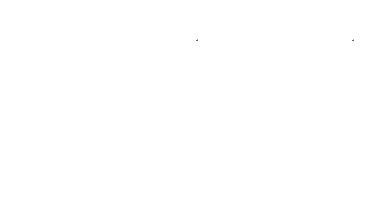

%%%%%%%%%%%%%%%%%%%%%%
%%% plot
%%% we want a 5 x 2 plot, so we'll make 2 columns (PM2.5, ozone) for:
%%% 1. SDK
%%% 2. Bronx
%%% 3. Manhattan
%%% 4. Queens
%%%%%%%%%%%%%%%%%%%%%%

%% figure attributes
colors = [213, 94, 0;  % red, long-term cf
          230, 159, 0; % yellow, CAIR
          150, 150, 150;  % gray, other
          0, 114, 178;  % blue, short-term cf
          70, 70, 70]/255;      % gray, observed
xlims = datetime([2006, 2020], 1, 1);
xtickss = datetime(2006, 1, 1):calyears(2):datetime(2020, 1, 1);
fontSize = 30;
lineWidth = 5;
aspect_ratio = [2.5, 1, 1];

%% 1. SDK
fig_SDK = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact");
% a. PM2.5
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.SDK_pm25.Date, pollutants_total_diff.SDK_pm25.median, ...
    [pollutants_total_diff.SDK_pm25.median - pollutants_total_diff.SDK_pm25.lower_bound, ...
    pollutants_total_diff.SDK_pm25.upper_bound - pollutants_total_diff.SDK_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.SDK_pm25.Date, pollutants_CAIR_diff.SDK_pm25.median, ...
    [pollutants_CAIR_diff.SDK_pm25.median - pollutants_CAIR_diff.SDK_pm25.lower_bound, ...
    pollutants_CAIR_diff.SDK_pm25.upper_bound - pollutants_CAIR_diff.SDK_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.SDK_pm25.Date, pollutants_other_diff.SDK_pm25.median, ...
    [pollutants_other_diff.SDK_pm25.median - pollutants_other_diff.SDK_pm25.lower_bound, ...
    pollutants_other_diff.SDK_pm25.upper_bound - pollutants_other_diff.SDK_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.SDK_pm25.Date, pollutants_short_diff.SDK_pm25.median, ...
    [pollutants_short_diff.SDK_pm25.median - pollutants_short_diff.SDK_pm25.lower_bound, ...
    pollutants_short_diff.SDK_pm25.upper_bound - pollutants_short_diff.SDK_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-10, 1])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'PM2.5';'(\mug/m^3)'})

hold off

% b. ozone
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.SDK_ozone.Date, pollutants_total_diff.SDK_ozone.median, ...
    [pollutants_total_diff.SDK_ozone.median - pollutants_total_diff.SDK_ozone.lower_bound, ...
    pollutants_total_diff.SDK_ozone.upper_bound - pollutants_total_diff.SDK_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.SDK_ozone.Date, pollutants_CAIR_diff.SDK_ozone.median, ...
    [pollutants_CAIR_diff.SDK_ozone.median - pollutants_CAIR_diff.SDK_ozone.lower_bound, ...
    pollutants_CAIR_diff.SDK_ozone.upper_bound - pollutants_CAIR_diff.SDK_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.SDK_ozone.Date, pollutants_other_diff.SDK_ozone.median, ...
    [pollutants_other_diff.SDK_ozone.median - pollutants_other_diff.SDK_ozone.lower_bound, ...
    pollutants_other_diff.SDK_ozone.upper_bound - pollutants_other_diff.SDK_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.SDK_ozone.Date, pollutants_short_diff.SDK_ozone.median, ...
    [pollutants_short_diff.SDK_ozone.median - pollutants_short_diff.SDK_ozone.lower_bound, ...
    pollutants_short_diff.SDK_ozone.upper_bound - pollutants_short_diff.SDK_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-5.6, 5.6])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'\DeltaOzone'; '(ppb)'})

hold off

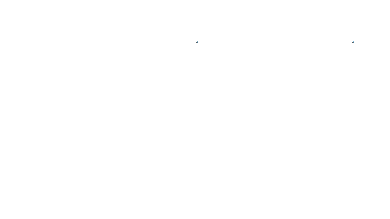

%% 2. Bronx
fig_Bronx = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact");
% a. PM2.5
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Bronx_pm25.Date, pollutants_total_diff.Bronx_pm25.median, ...
    [pollutants_total_diff.Bronx_pm25.median - pollutants_total_diff.Bronx_pm25.lower_bound, ...
    pollutants_total_diff.Bronx_pm25.upper_bound - pollutants_total_diff.Bronx_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Bronx_pm25.Date, pollutants_CAIR_diff.Bronx_pm25.median, ...
    [pollutants_CAIR_diff.Bronx_pm25.median - pollutants_CAIR_diff.Bronx_pm25.lower_bound, ...
    pollutants_CAIR_diff.Bronx_pm25.upper_bound - pollutants_CAIR_diff.Bronx_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Bronx_pm25.Date, pollutants_other_diff.Bronx_pm25.median, ...
    [pollutants_other_diff.Bronx_pm25.median - pollutants_other_diff.Bronx_pm25.lower_bound, ...
    pollutants_other_diff.Bronx_pm25.upper_bound - pollutants_other_diff.Bronx_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Bronx_pm25.Date, pollutants_short_diff.Bronx_pm25.median, ...
    [pollutants_short_diff.Bronx_pm25.median - pollutants_short_diff.Bronx_pm25.lower_bound, ...
    pollutants_short_diff.Bronx_pm25.upper_bound - pollutants_short_diff.Bronx_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-10, 1])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'PM2.5';'(\mug/m^3)'})

hold off

% b. ozone
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Bronx_ozone.Date, pollutants_total_diff.Bronx_ozone.median, ...
    [pollutants_total_diff.Bronx_ozone.median - pollutants_total_diff.Bronx_ozone.lower_bound, ...
    pollutants_total_diff.Bronx_ozone.upper_bound - pollutants_total_diff.Bronx_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Bronx_ozone.Date, pollutants_CAIR_diff.Bronx_ozone.median, ...
    [pollutants_CAIR_diff.Bronx_ozone.median - pollutants_CAIR_diff.Bronx_ozone.lower_bound, ...
    pollutants_CAIR_diff.Bronx_ozone.upper_bound - pollutants_CAIR_diff.Bronx_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Bronx_ozone.Date, pollutants_other_diff.Bronx_ozone.median, ...
    [pollutants_other_diff.Bronx_ozone.median - pollutants_other_diff.Bronx_ozone.lower_bound, ...
    pollutants_other_diff.Bronx_ozone.upper_bound - pollutants_other_diff.Bronx_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Bronx_ozone.Date, pollutants_short_diff.Bronx_ozone.median, ...
    [pollutants_short_diff.Bronx_ozone.median - pollutants_short_diff.Bronx_ozone.lower_bound, ...
    pollutants_short_diff.Bronx_ozone.upper_bound - pollutants_short_diff.Bronx_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-2, 8])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'\DeltaOzone'; '(ppb)'})

hold off

%% 3. Manhattan
fig_Manhattan = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact");
% a. PM2.5
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Manhattan_pm25.Date, pollutants_total_diff.Manhattan_pm25.median, ...
    [pollutants_total_diff.Manhattan_pm25.median - pollutants_total_diff.Manhattan_pm25.lower_bound, ...
    pollutants_total_diff.Manhattan_pm25.upper_bound - pollutants_total_diff.Manhattan_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Manhattan_pm25.Date, pollutants_CAIR_diff.Manhattan_pm25.median, ...
    [pollutants_CAIR_diff.Manhattan_pm25.median - pollutants_CAIR_diff.Manhattan_pm25.lower_bound, ...
    pollutants_CAIR_diff.Manhattan_pm25.upper_bound - pollutants_CAIR_diff.Manhattan_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Manhattan_pm25.Date, pollutants_other_diff.Manhattan_pm25.median, ...
    [pollutants_other_diff.Manhattan_pm25.median - pollutants_other_diff.Manhattan_pm25.lower_bound, ...
    pollutants_other_diff.Manhattan_pm25.upper_bound - pollutants_other_diff.Manhattan_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Manhattan_pm25.Date, pollutants_short_diff.Manhattan_pm25.median, ...
    [pollutants_short_diff.Manhattan_pm25.median - pollutants_short_diff.Manhattan_pm25.lower_bound, ...
    pollutants_short_diff.Manhattan_pm25.upper_bound - pollutants_short_diff.Manhattan_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-12.5, 1])
yticks(-12:6:0)

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'PM2.5';'(\mug/m^3)'})

hold off

% b. ozone
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Manhattan_ozone.Date, pollutants_total_diff.Manhattan_ozone.median, ...
    [pollutants_total_diff.Manhattan_ozone.median - pollutants_total_diff.Manhattan_ozone.lower_bound, ...
    pollutants_total_diff.Manhattan_ozone.upper_bound - pollutants_total_diff.Manhattan_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Manhattan_ozone.Date, pollutants_CAIR_diff.Manhattan_ozone.median, ...
    [pollutants_CAIR_diff.Manhattan_ozone.median - pollutants_CAIR_diff.Manhattan_ozone.lower_bound, ...
    pollutants_CAIR_diff.Manhattan_ozone.upper_bound - pollutants_CAIR_diff.Manhattan_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Manhattan_ozone.Date, pollutants_other_diff.Manhattan_ozone.median, ...
    [pollutants_other_diff.Manhattan_ozone.median - pollutants_other_diff.Manhattan_ozone.lower_bound, ...
    pollutants_other_diff.Manhattan_ozone.upper_bound - pollutants_other_diff.Manhattan_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Manhattan_ozone.Date, pollutants_short_diff.Manhattan_ozone.median, ...
    [pollutants_short_diff.Manhattan_ozone.median - pollutants_short_diff.Manhattan_ozone.lower_bound, ...
    pollutants_short_diff.Manhattan_ozone.upper_bound - pollutants_short_diff.Manhattan_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-5, 5.5])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'\DeltaOzone'; '(ppb)'})

hold off

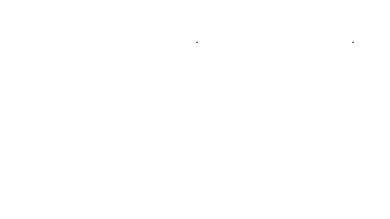

%% 4. Queens
fig_Queens = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(1, 2, "TileSpacing", "compact");
% a. PM2.5
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Queens_pm25.Date, pollutants_total_diff.Queens_pm25.median, ...
    [pollutants_total_diff.Queens_pm25.median - pollutants_total_diff.Queens_pm25.lower_bound, ...
    pollutants_total_diff.Queens_pm25.upper_bound - pollutants_total_diff.Queens_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Queens_pm25.Date, pollutants_CAIR_diff.Queens_pm25.median, ...
    [pollutants_CAIR_diff.Queens_pm25.median - pollutants_CAIR_diff.Queens_pm25.lower_bound, ...
    pollutants_CAIR_diff.Queens_pm25.upper_bound - pollutants_CAIR_diff.Queens_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Queens_pm25.Date, pollutants_other_diff.Queens_pm25.median, ...
    [pollutants_other_diff.Queens_pm25.median - pollutants_other_diff.Queens_pm25.lower_bound, ...
    pollutants_other_diff.Queens_pm25.upper_bound - pollutants_other_diff.Queens_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Queens_pm25.Date, pollutants_short_diff.Queens_pm25.median, ...
    [pollutants_short_diff.Queens_pm25.median - pollutants_short_diff.Queens_pm25.lower_bound, ...
    pollutants_short_diff.Queens_pm25.upper_bound - pollutants_short_diff.Queens_pm25.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-10, 1])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'PM2.5';'(\mug/m^3)'})

hold off

% b. ozone
ax = nexttile;
hold on
box on
pbaspect(aspect_ratio)

yline(0, '-', 'Color', [0.7, 0.7, 0.7], LineWidth=0.5)

% total counterfactual
boundedline(pollutants_total_diff.Queens_ozone.Date, pollutants_total_diff.Queens_ozone.median, ...
    [pollutants_total_diff.Queens_ozone.median - pollutants_total_diff.Queens_ozone.lower_bound, ...
    pollutants_total_diff.Queens_ozone.upper_bound - pollutants_total_diff.Queens_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(1, :));
% CAIR
boundedline(pollutants_CAIR_diff.Queens_ozone.Date, pollutants_CAIR_diff.Queens_ozone.median, ...
    [pollutants_CAIR_diff.Queens_ozone.median - pollutants_CAIR_diff.Queens_ozone.lower_bound, ...
    pollutants_CAIR_diff.Queens_ozone.upper_bound - pollutants_CAIR_diff.Queens_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(2, :));
% CSAPR, MATS, and other
boundedline(pollutants_other_diff.Queens_ozone.Date, pollutants_other_diff.Queens_ozone.median, ...
    [pollutants_other_diff.Queens_ozone.median - pollutants_other_diff.Queens_ozone.lower_bound, ...
    pollutants_other_diff.Queens_ozone.upper_bound - pollutants_other_diff.Queens_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(3, :));
% short-run counterfactual
boundedline(pollutants_short_diff.Queens_ozone.Date, pollutants_short_diff.Queens_ozone.median, ...
    [pollutants_short_diff.Queens_ozone.median - pollutants_short_diff.Queens_ozone.lower_bound, ...
    pollutants_short_diff.Queens_ozone.upper_bound - pollutants_short_diff.Queens_ozone.median], 'LineWidth', lineWidth,...
    'nan', 'gap', 'alpha', 'transparency', 0.1, ...
    'color', colors(4, :));

% lims and ticks
xlim(datenum(xlims))
xticks(datenum(xtickss))
ax.XTickLabel = datestr(xtickss, "yyyy");
ylim([-2, 8])

% labels
ax.FontSize = fontSize;
xlabel("Year")
ylabel({'\DeltaOzone'; '(ppb)'})

hold off

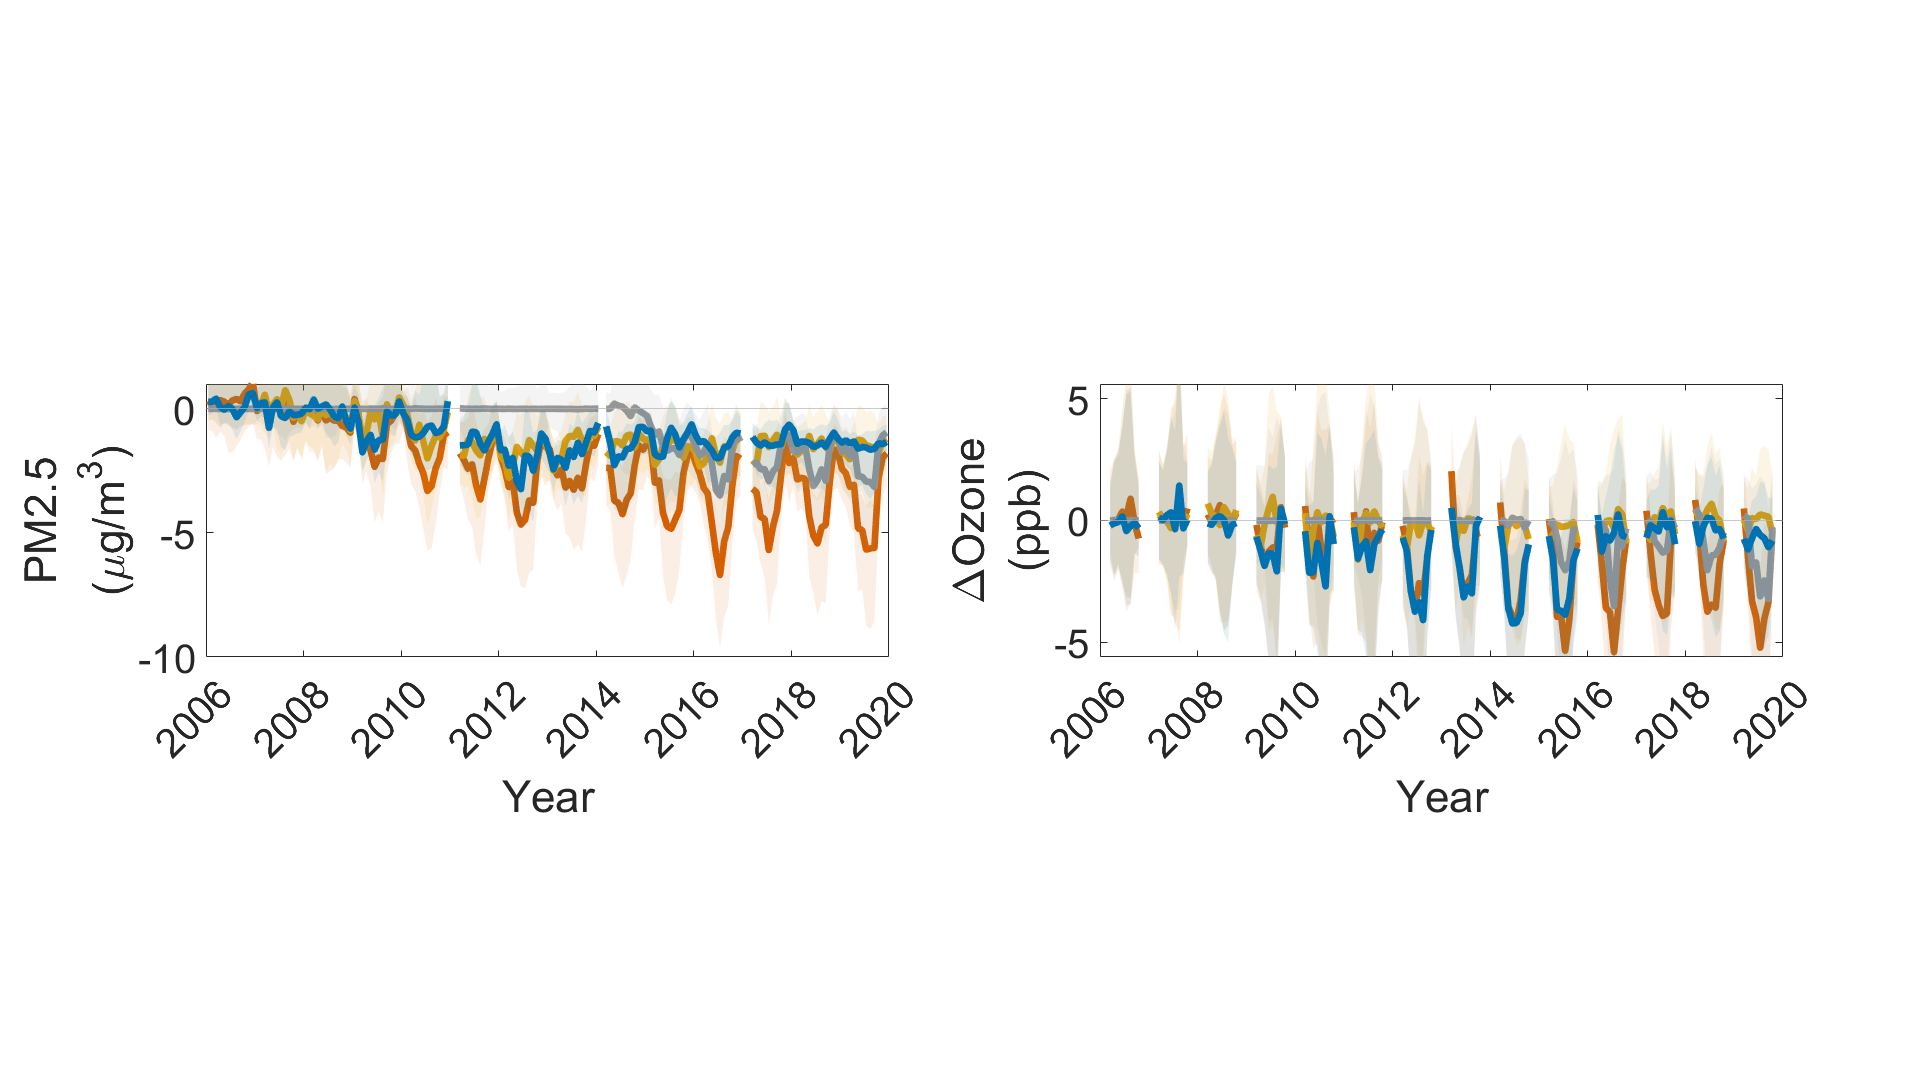

%%%%%%%%%%%%%%%%%%%%%%
%%% export
%%%%%%%%%%%%%%%%%%%%%%
fn_beg = "sup_fig_pollutants_reductions";
cd(fp)
cd(rel_path_output)
exportgraphics(fig_SDK, strcat(fn_beg, "_SDK.png"));

exportgraphics(fig_Bronx, strcat(fn_beg, "_Bronx.png"));

exportgraphics(fig_Manhattan, strcat(fn_beg, "_Manhattan.png"));

exportgraphics(fig_Queens, strcat(fn_beg, "_Queens.png"));

function [output] = binCounterfactual(input, spacing)
% input is input table that has Date, lower_bound, upper_bound, and median
% spacing is bin edges in datenum

% median
[median, ~, ~, timeSpacing] = BinAvg(datenum(input.Date), input.median, ...
    spacing, 15, 3);
% lower bound
[lower_bound, ~, ~, ~] = BinAvg(datenum(input.Date), input.lower_bound, ...
    spacing, 15, 3);
% upper bound
[upper_bound, ~, ~, ~] = BinAvg(datenum(input.Date), input.upper_bound, ...
    spacing, 15, 3);

output = table(timeSpacing, median, lower_bound, upper_bound);
output.Properties.VariableNames = ["Date", "median", "lower_bound", "upper_bound"];

end

function [output] = subtractTableAndMakeNegative(input, to_subtract)
% subtracts constant value from all others in a table (with median,
% lower_bound, and upper_bound
output = input;
output.median = -1*(output.median - to_subtract);
output.lower_bound = -1*(output.lower_bound - to_subtract);
output.upper_bound = -1*(output.upper_bound - to_subtract);
end